% NOTE: IF DATA IS LOCALLY AVAILABLE, build all_stacks_data struct
% root_dir = '.';
% cd(root_dir)
% all_stacks_data = compare_samples(root_dir, {'EF.mat', 'B.mat', 'L.mat', 'BL.mat'}, cell(1, 4));

EF.mat
B.mat
L.mat
BL.mat


% save('all_stacks_data.mat', 'all_stacks_data')

% Load previously saved all_stacks_data struct which contains counts
% information and other data extracted from seqRNA-FISH images
root_dir = '.';
cd(root_dir)
temp = load('all_stacks_data.mat');
all_stacks_data = temp.all_stacks_data;

% consolidate data into a MATLAB table format
gene_list = {'Hes1', 'Hes5', 'Hey1', 'Id1', 'Id2', 'Id3', 'Id4', 'Tcf3', 'Tcf4', 'Tcf12', 'Olig1', 'Olig2', 'Ascl1', 'Atoh8'};
dot_data_tables = consolidate_data(all_stacks_data, gene_list, 'count', []);
sample_labels = {'EF', 'B', 'L', 'BL'};
gene_labels = all_stacks_data.gene_labels{1};


## Boxplot/Violinplot comparison of transcript levels

## **(Figure S3A)**

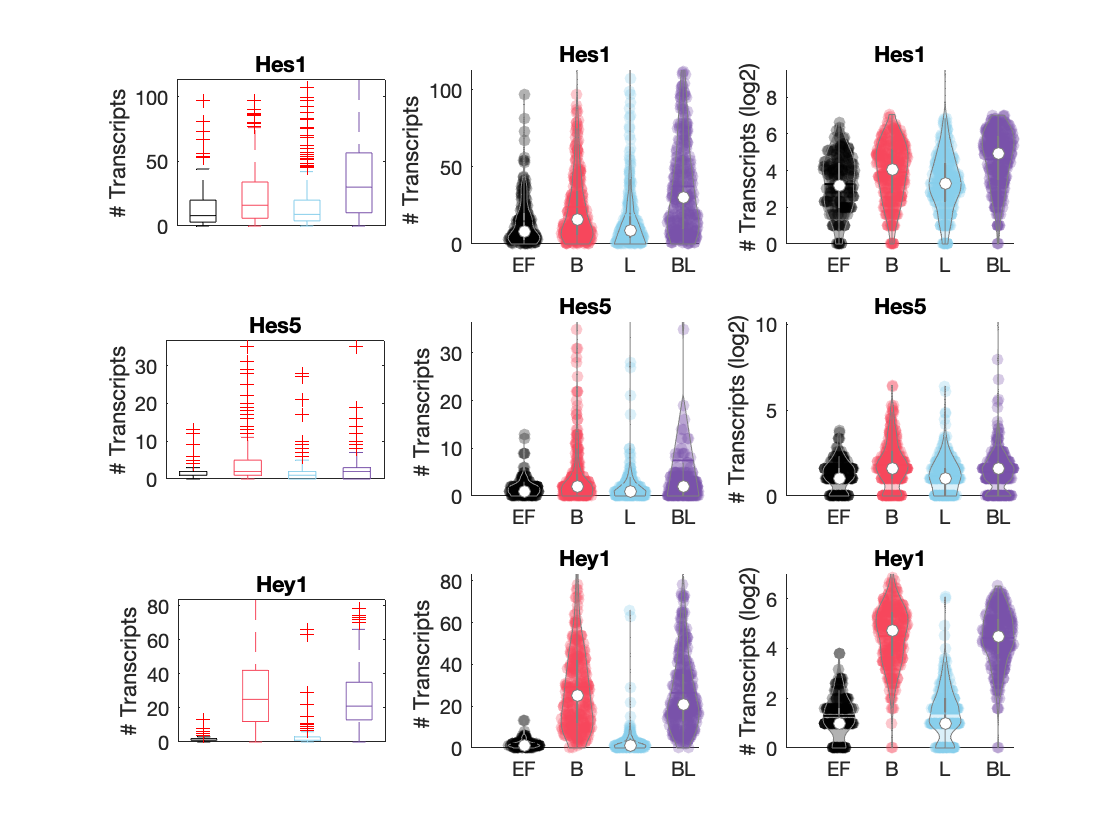

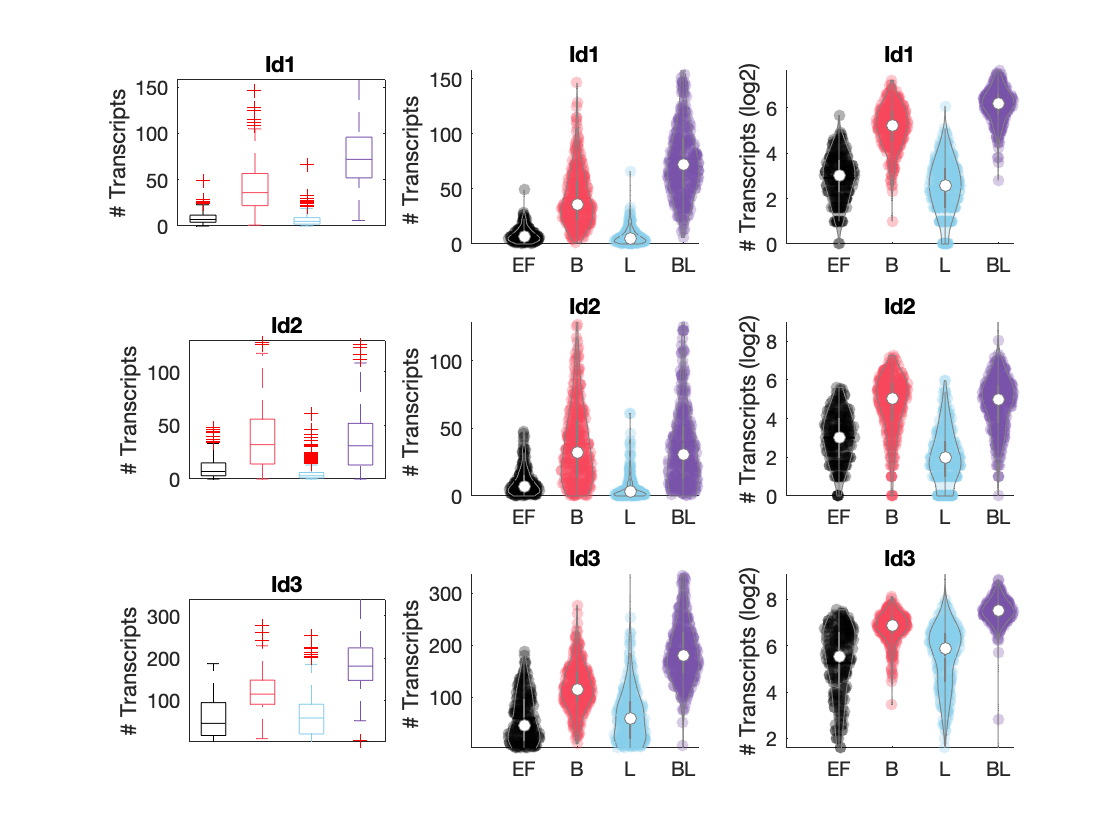

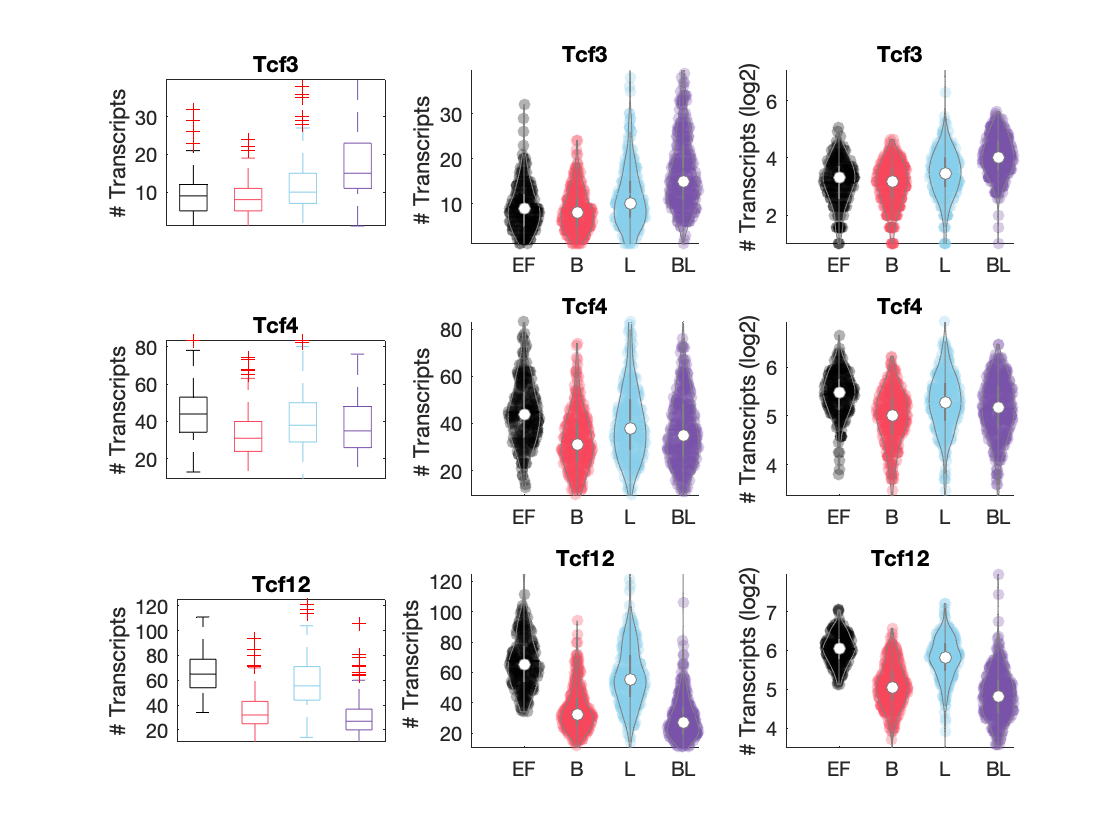

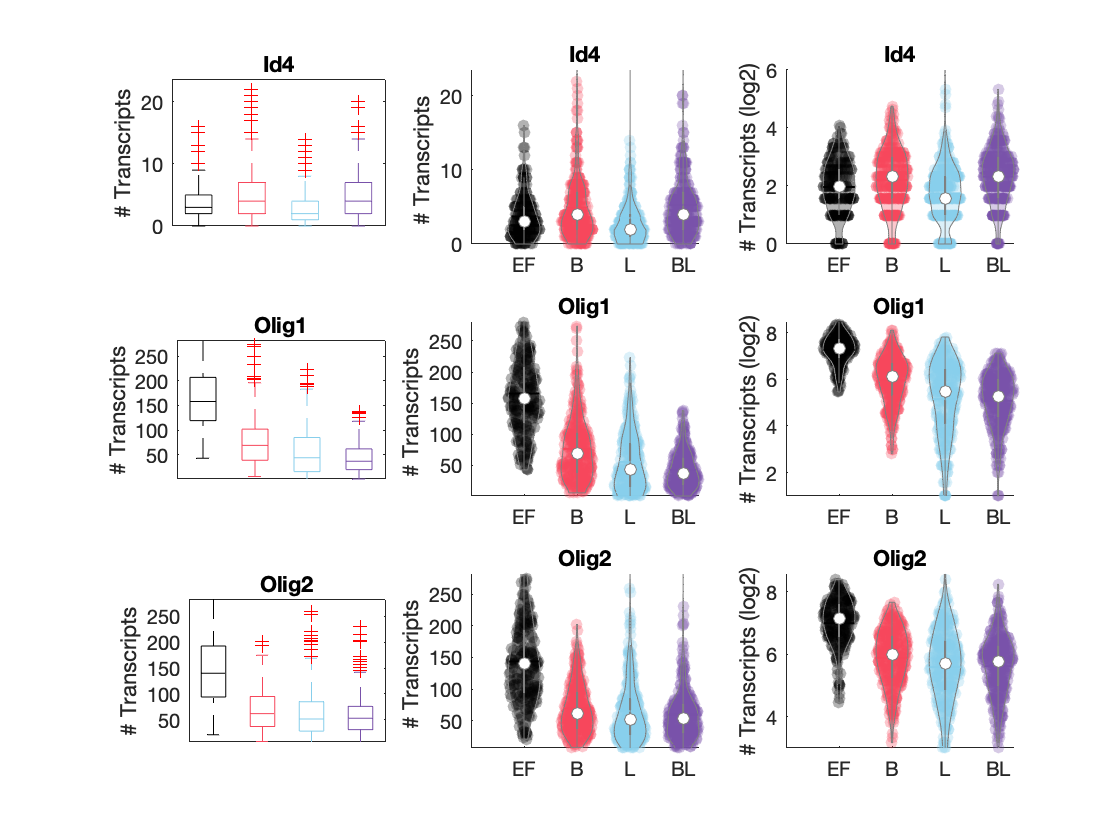

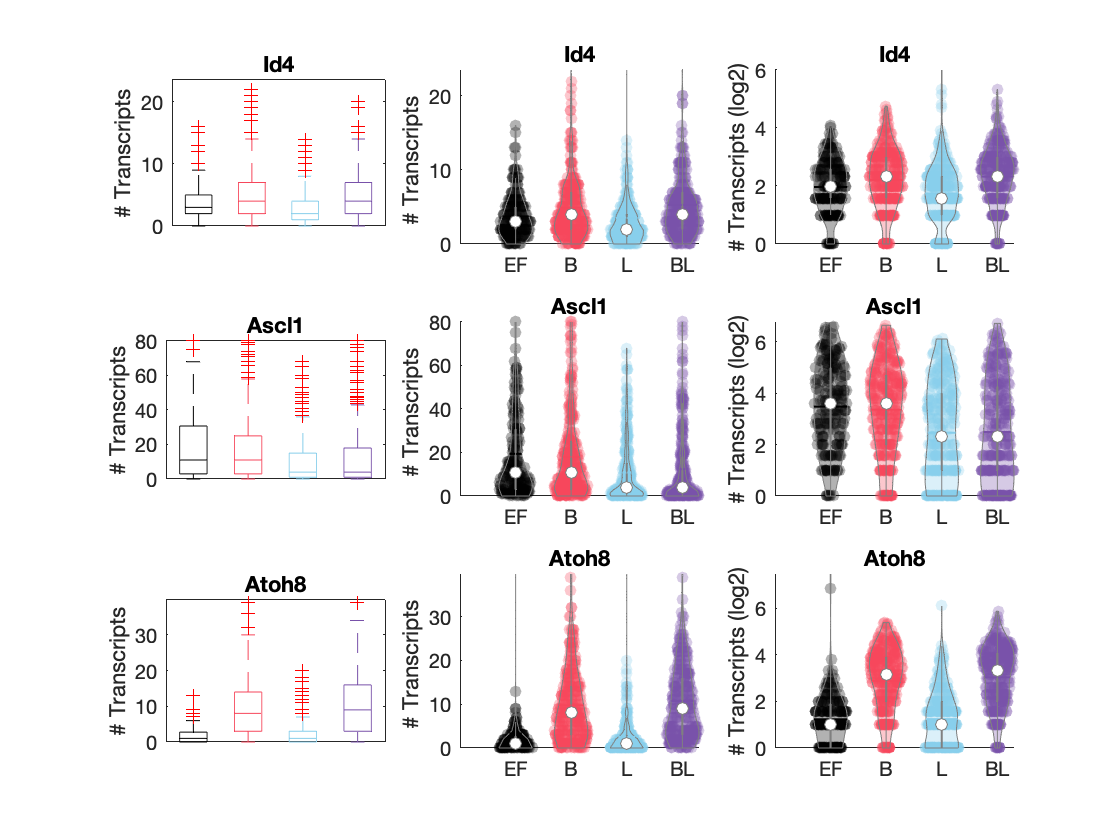

% Note that data acquired using an improved probeset was used for Olig2 in the manuscript 
% uses violinplot function by Bastian Bechtold 2016
sample_colors = [0 0 0; 246 70 91; 135 206 235;  120 81 169]/255;
save_state = false;
[ks_data, all_dot_data, all_dot_labels] = boxplot_comparison(all_stacks_data, gene_list, {[1, 2, 3, 4]}, sample_colors, {[1, 2, 3], [4, 5, 6], [8, 9, 10], [7, 11, 12], [7, 13, 14]}, 'count', sample_labels, save_state);

## Arc plots

## (Figure 2C, S3A, B)

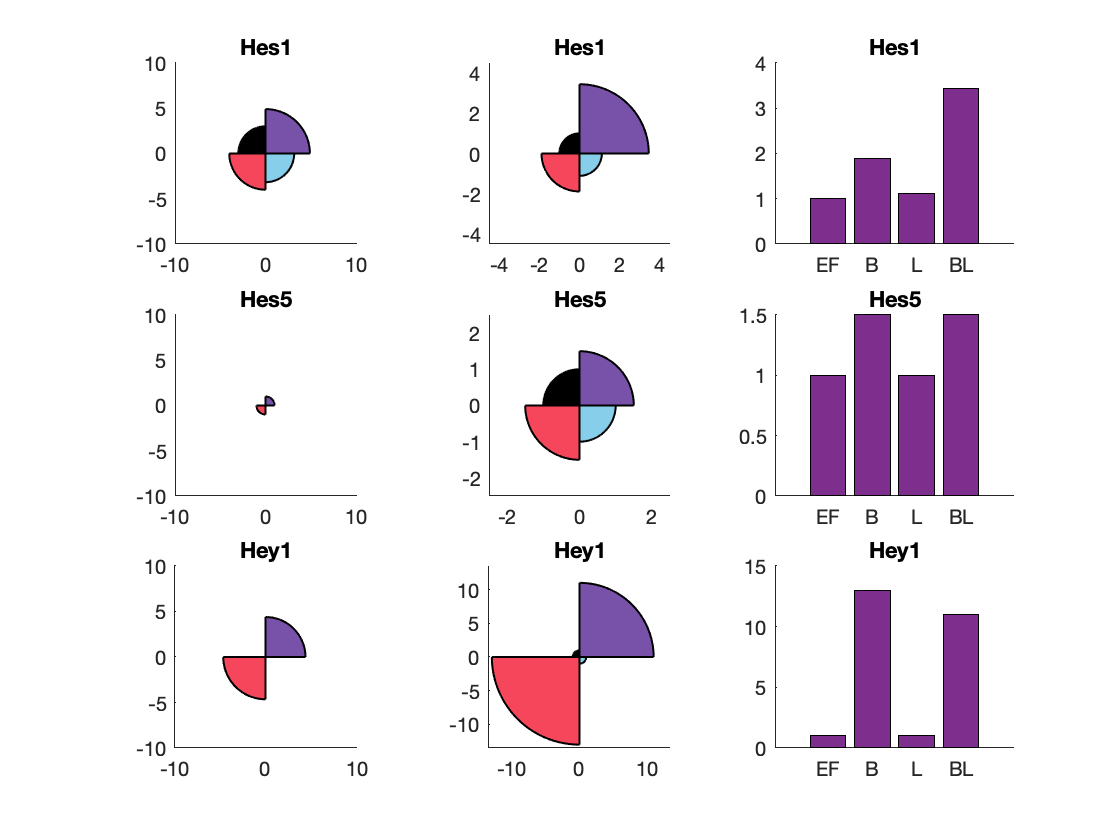

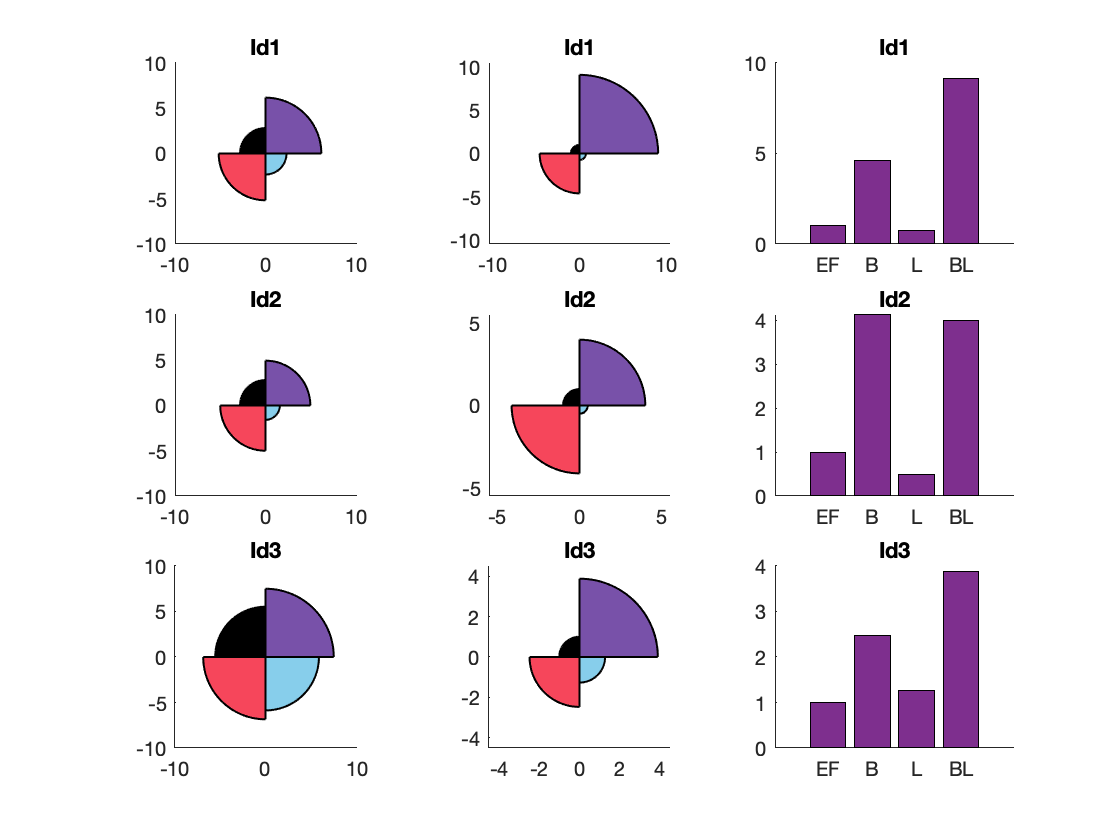

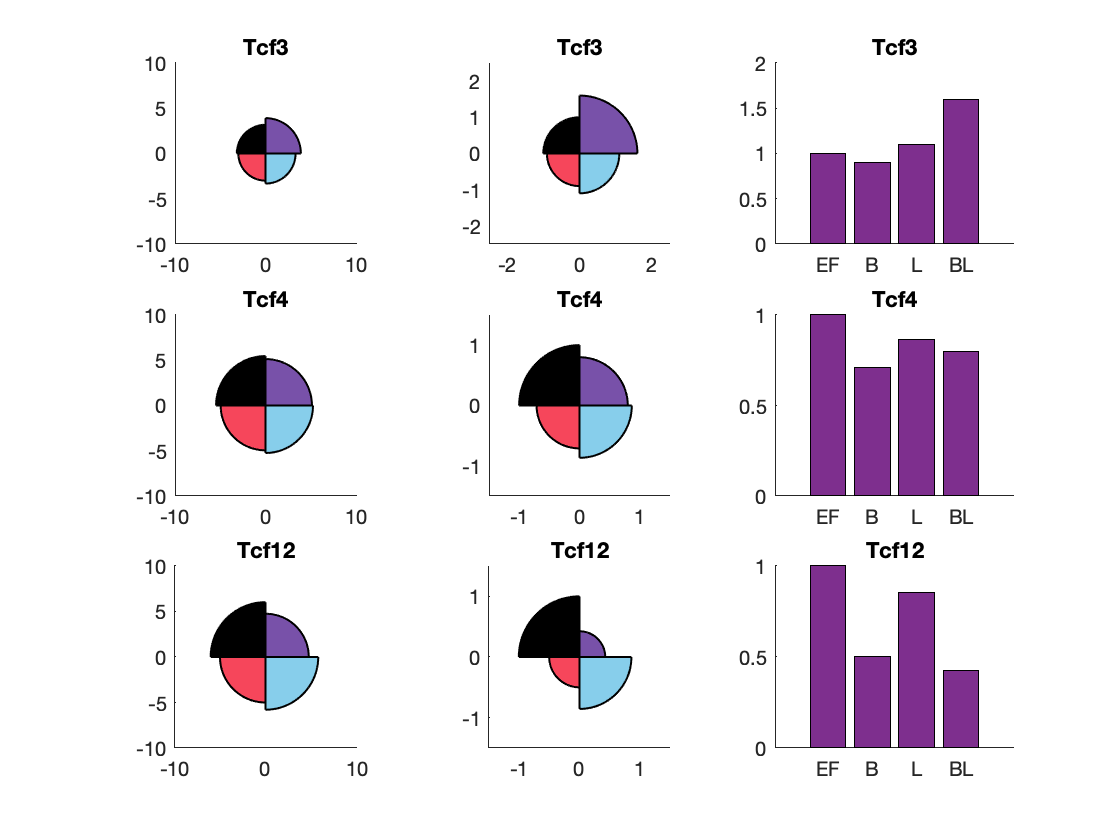

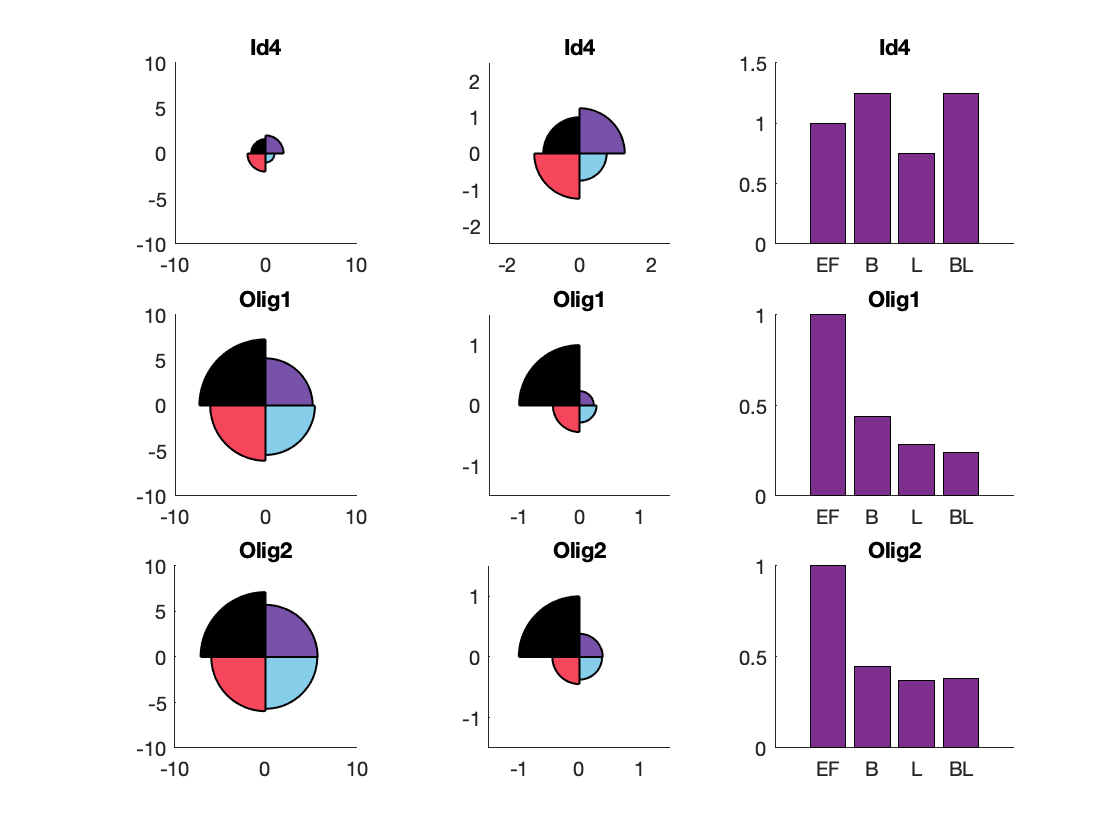

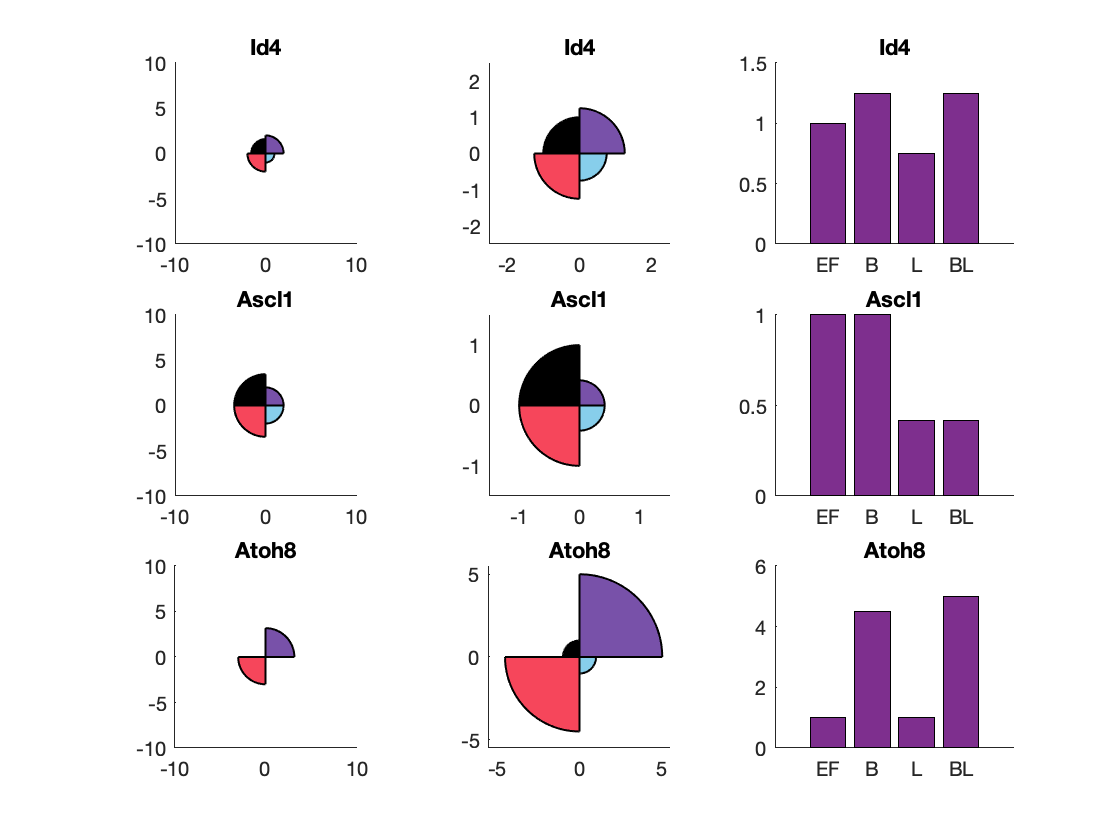

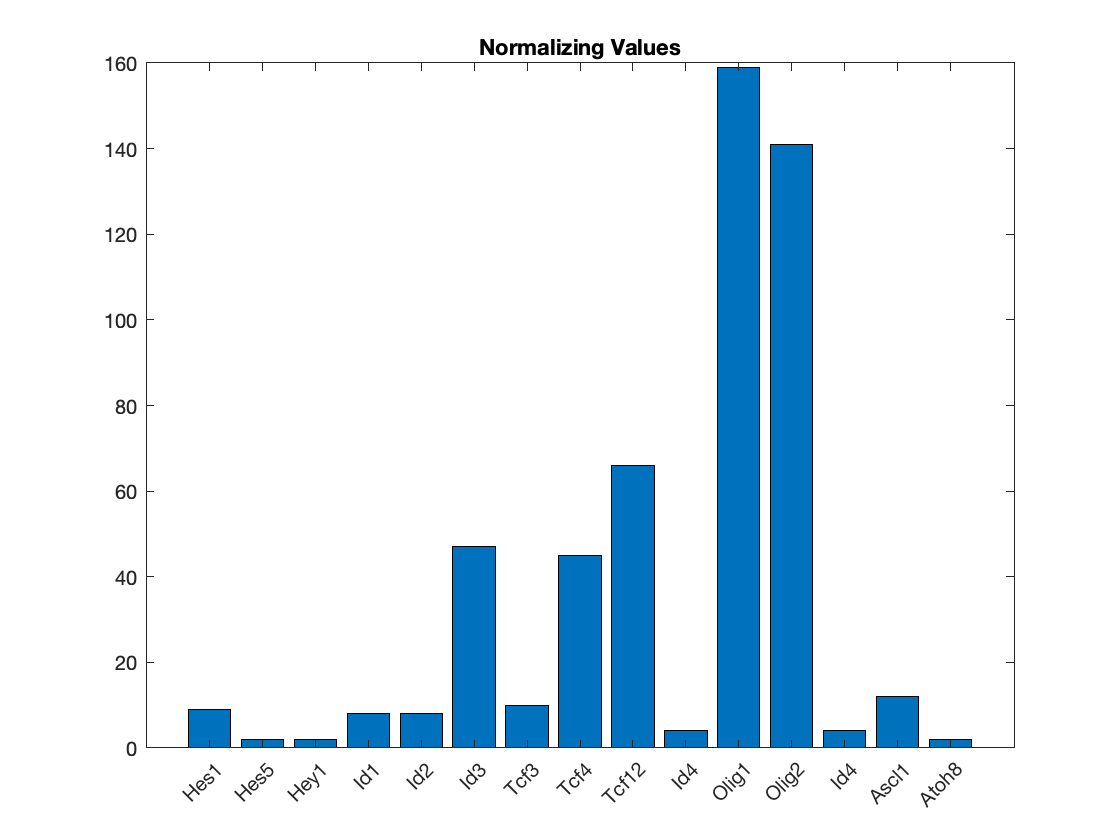

sample_colors = [0 0 0; 246 70 91; 135 206 235;  120 81 169]/255;
save_state = false;
norm_sample_num = 1;
norm_type = 'median';
arcplot_comparison(all_stacks_data, gene_list, {[1, 2, 3, 4]}, sample_colors, {[1, 2, 3], [4, 5, 6], [8, 9, 10], [7, 11, 12], [7, 13, 14]}, 'count', sample_labels, norm_type, norm_sample_num, save_state);